Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;
close all;

#### Initialize parameters of the model and instantiate model class

ell     = 1.0;
m       = 1.0;
gravity = 9.81;
ode     = CrankRod14EQ( ell, m, gravity );

#### Initialize the solver class

solver_1 = ExplicitEuler();
solver_2 = ImplicitEuler();
solver_3 = Heun();

LEGEND = {'ExplicitEuler', 'ImplicitEuler', 'Heun'};

solver_1.setODE(ode);
solver_2.setODE(ode);
solver_3.setODE(ode);

#### **Select the range and the sampling point for the numerical solution**

Tmax = 7.5;
h    = 0.05;
tt   = 0:h:Tmax;

#### Set consistent initial conditions

angle     = -pi/4;
speed     = 0.0;

x_10      = ell*cos(angle);
y_10      = ell*sin(angle);
x_20      = 2*ell*cos(angle);
y_20      = 0;
theta_0   = angle;
u_10      = -speed*ell*sin(angle);
v_10      = speed*ell*cos(angle);
u_20      = -2*speed*ell*sin(angle);
v_20      = 0;
omega_0   = speed;
lambda_10 = -3*m*cos(angle)*(ell*(speed^2)-gravity*sin(angle))*(1/(4*sin(angle)^2+1));
lambda_20 = -5*m*sin(angle)*(ell*(speed^2)-gravity*sin(angle))*(1/(4*sin(angle)^2+1));
lambda_30 = -2*m*cos(angle)*(ell*(speed^2)-gravity*sin(angle))*(1/(4*sin(angle)^2+1));
lambda_40 = m*gravity;
ini       = [ x_10; y_10; x_20; y_20; theta_0; ...
              u_10; v_10; u_20; v_20; omega_0;...
              lambda_10; lambda_20; lambda_30; lambda_40; ];

#### **Compute numerical solution**

sol_1 = solver_1.advance( tt, ini );
sol_2 = solver_2.advance( tt, ini );
sol_3 = solver_3.advance( tt, ini );

#### Extract solution

x1_1    = sol_1(1,:);
y1_1    = sol_1(2,:);
x2_1    = sol_1(3,:);
y2_1    = sol_1(4,:);
theta_1 = sol_1(5,:);
u1_1    = sol_1(6,:);
v1_1    = sol_1(7,:);
u2_1    = sol_1(8,:);
v2_1    = sol_1(9,:);

x1_2    = sol_2(1,:);
y1_2    = sol_2(2,:);
x2_2    = sol_2(3,:);
y2_2    = sol_2(4,:);
theta_2 = sol_2(5,:);
u1_2    = sol_2(6,:);
v1_2    = sol_2(7,:);
u2_2    = sol_2(8,:);
v2_2    = sol_2(9,:);

x1_3    = sol_3(1,:);
y1_3    = sol_3(2,:);
x2_3    = sol_3(3,:);
y2_3    = sol_3(4,:);
theta_3 = sol_3(5,:);
u1_3    = sol_3(6,:);
v1_3    = sol_3(7,:);
u2_3    = sol_3(8,:);
v2_3    = sol_3(9,:);

#### Plot the solution

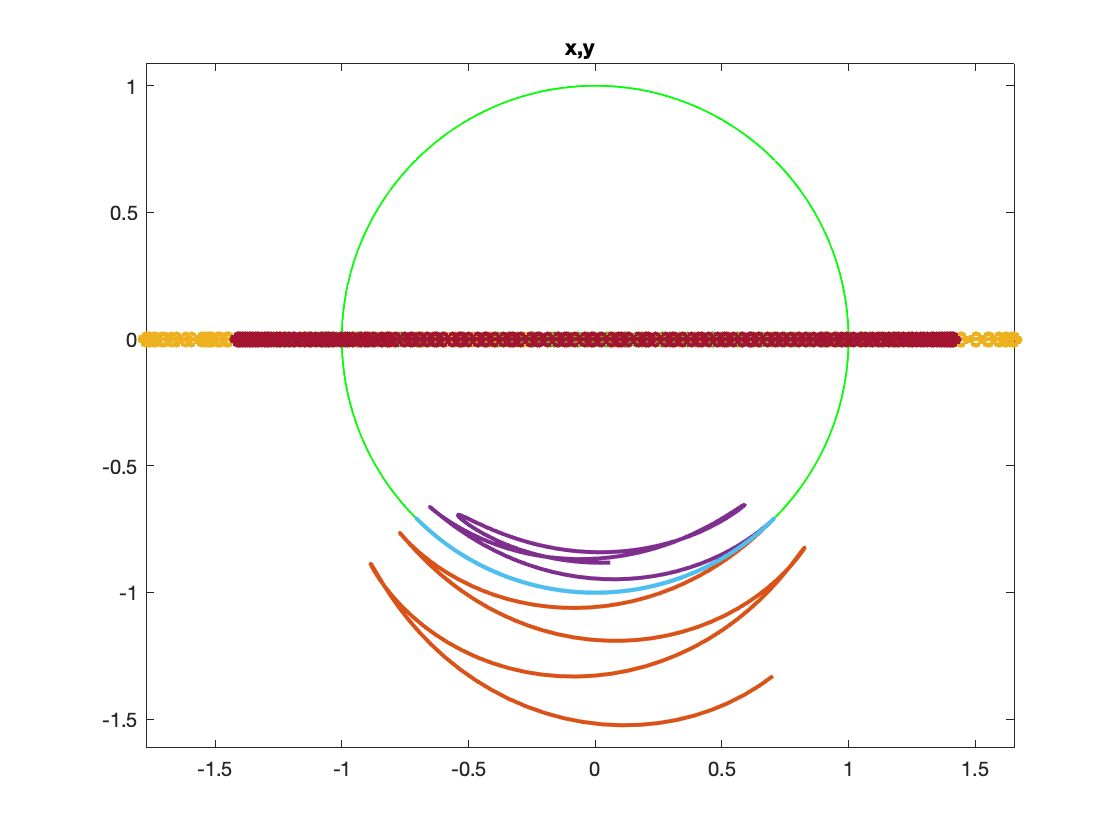

h = figure();
a = 0:0.01:2*pi;
plot( data.L1*cos(a), data.L1*sin(a), '-', 'Linewidth', 1, 'Color','green' );
hold on;
% get mass position

axis equal
plot( x1_1, y1_1, x2_1, y2_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x1_2, y1_2, x2_2, y2_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x1_3, y1_3, x2_3, y2_3,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

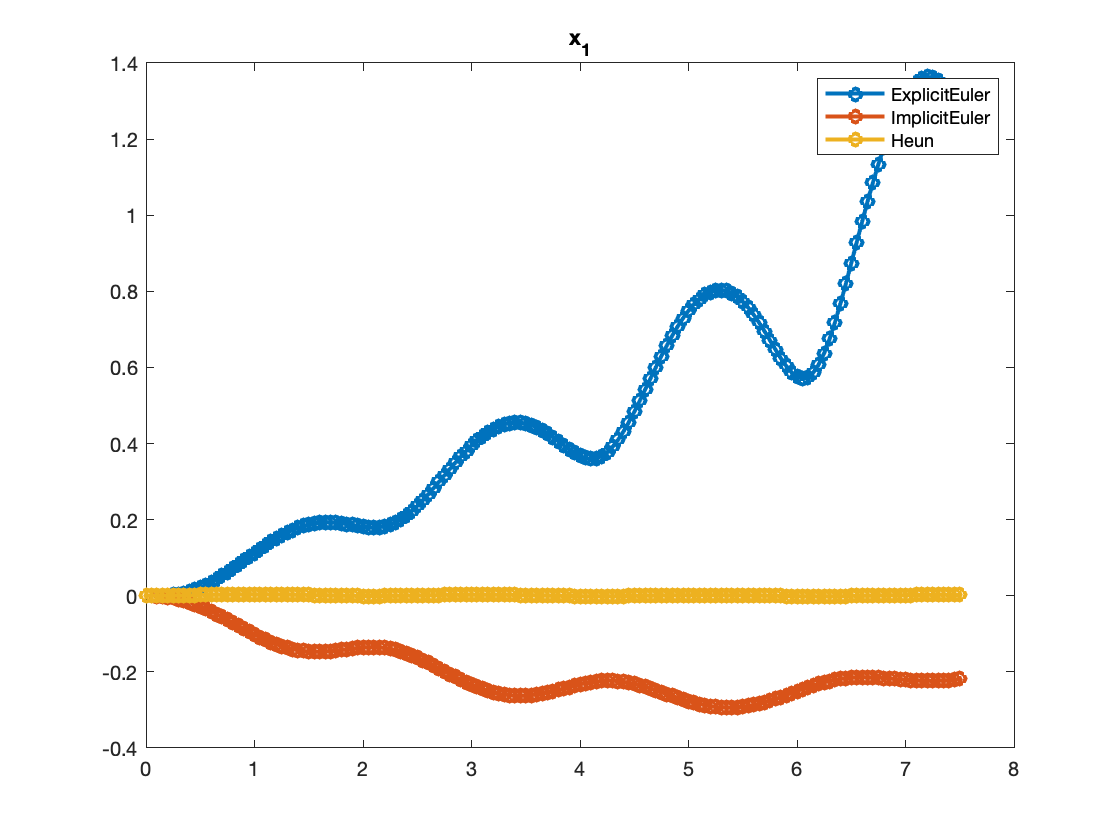

h = figure();
plot( tt, x1_1.^2+y1_1.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x1_2.^2+y1_2.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x1_3.^2+y1_3.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x_1');

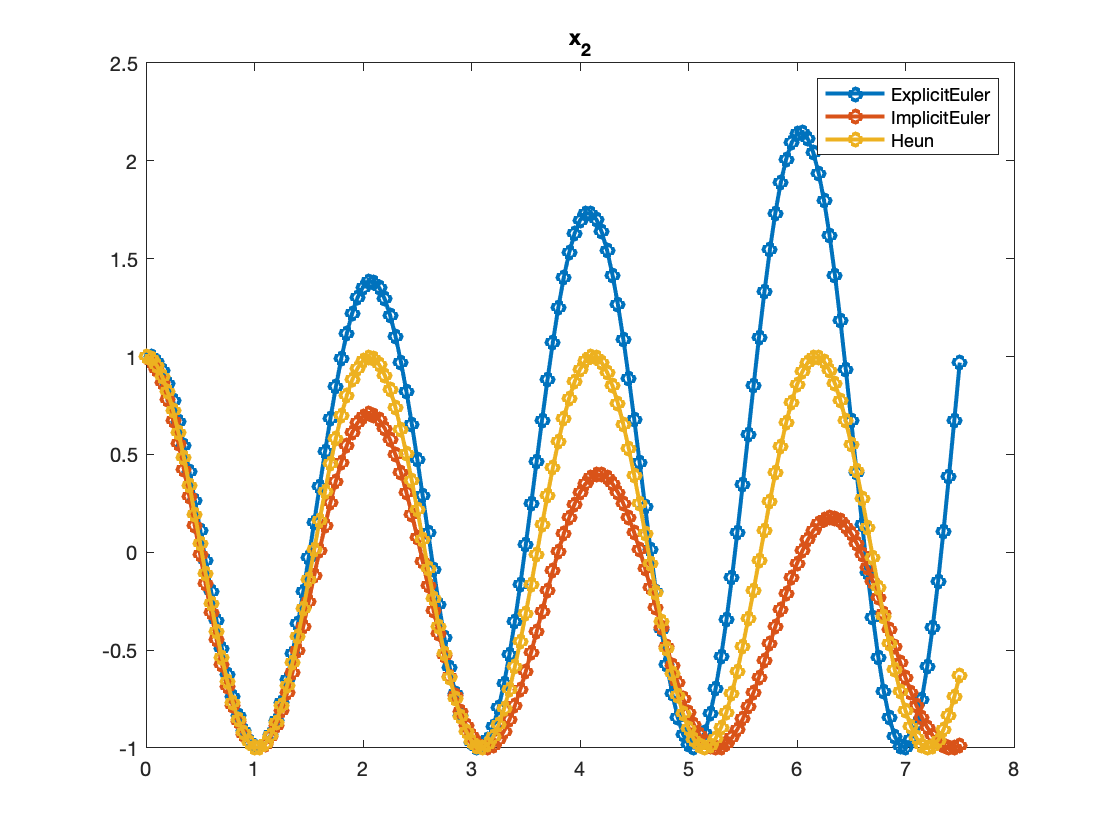

h = figure();
plot( tt, x2_1.^2+y2_1.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x2_2.^2+y2_2.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x2_3.^2+y2_3.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x_2');

### Make animation of the solution

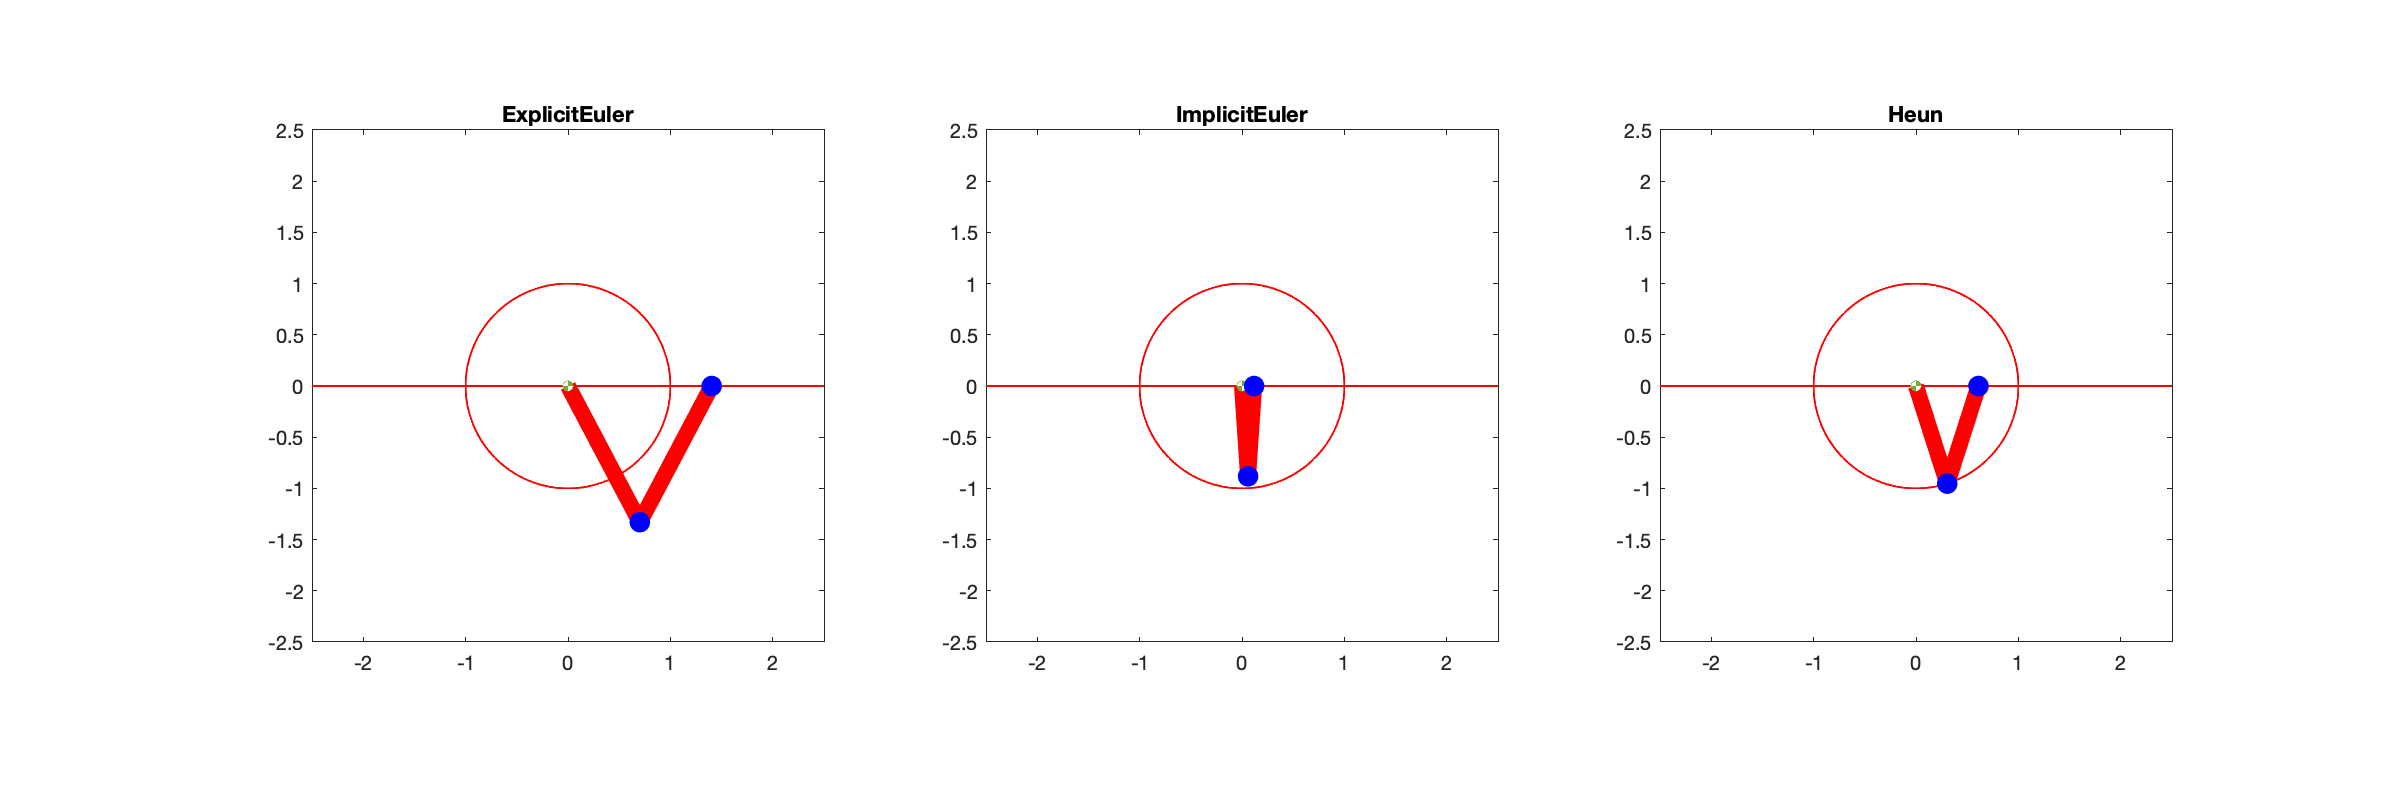

if true
  figure('Position', [1 1 1200 400]);
  for k=1:5:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end

### Compute solutions activating projection

sol_1 = solver_1.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_2 = solver_2.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


sol_3 = solver_3.advance( tt, ini, true, true );

  5%
 10%
 15%
 20%
 25%
 30%
 35%
 40%
 45%
 50%
 55%
 60%
 65%
 70%
 75%
 80%
 85%
 90%
 95%
100%


### Extract computed solution

x1_1    = sol_1(1,:);
y1_1    = sol_1(2,:);
x2_1    = sol_1(3,:);
y2_1    = sol_1(4,:);
theta_1 = sol_1(5,:);
u1_1    = sol_1(6,:);
v1_1    = sol_1(7,:);
u2_1    = sol_1(8,:);
v2_1    = sol_1(9,:);

x1_2    = sol_2(1,:);
y1_2    = sol_2(2,:);
x2_2    = sol_2(3,:);
y2_2    = sol_2(4,:);
theta_2 = sol_2(5,:);
u1_2    = sol_2(6,:);
v1_2    = sol_2(7,:);
u2_2    = sol_2(8,:);
v2_2    = sol_2(9,:);

x1_3    = sol_3(1,:);
y1_3    = sol_3(2,:);
x2_3    = sol_3(3,:);
y2_3    = sol_3(4,:);
theta_3 = sol_3(5,:);
u1_3    = sol_3(6,:);
v1_3    = sol_3(7,:);
u2_3    = sol_3(8,:);
v2_3    = sol_3(9,:);

#### Plot the solution

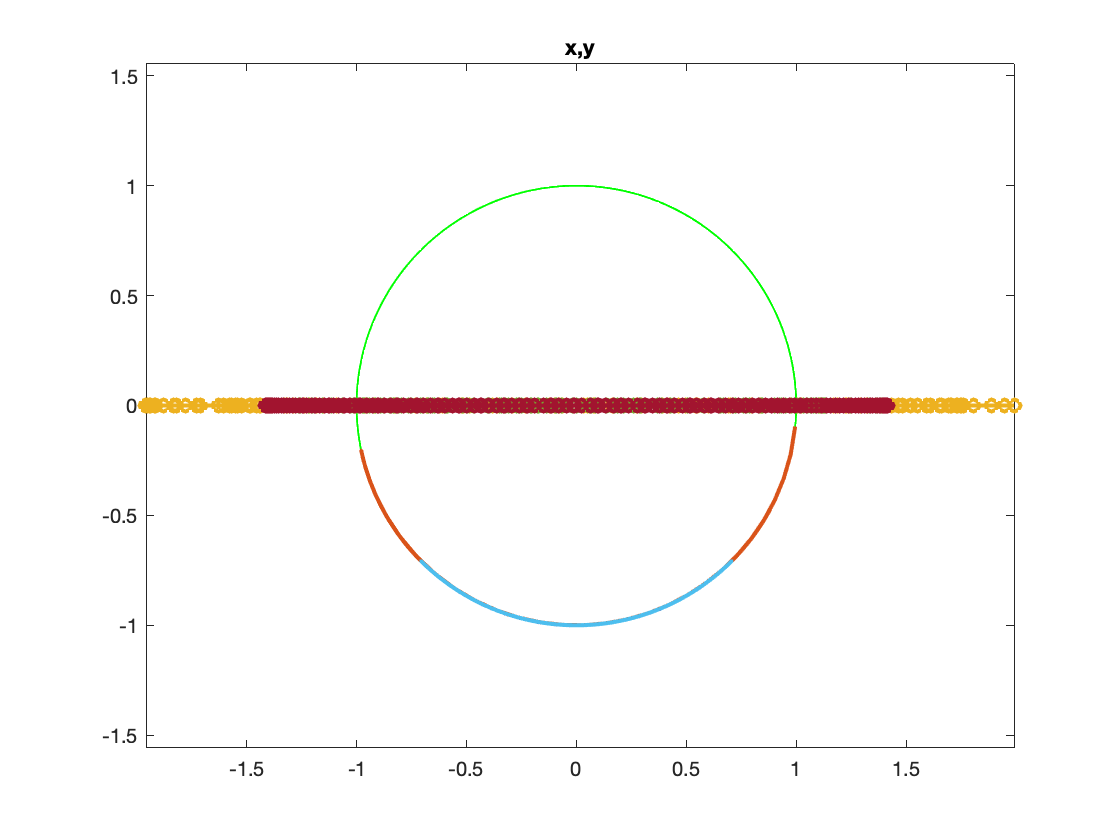

h = figure();
a = 0:0.01:2*pi;
plot( data.L1*cos(a), data.L1*sin(a), '-', 'Linewidth', 1, 'Color','green' );
hold on;
% get mass position

axis equal
plot( x1_1, y1_1, x2_1, y2_1, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x1_2, y1_2, x2_2, y2_2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( x1_3, y1_3, x2_3, y2_3,  '-o', 'MarkerSize', 6, 'Linewidth', 2 );
title('x,y');

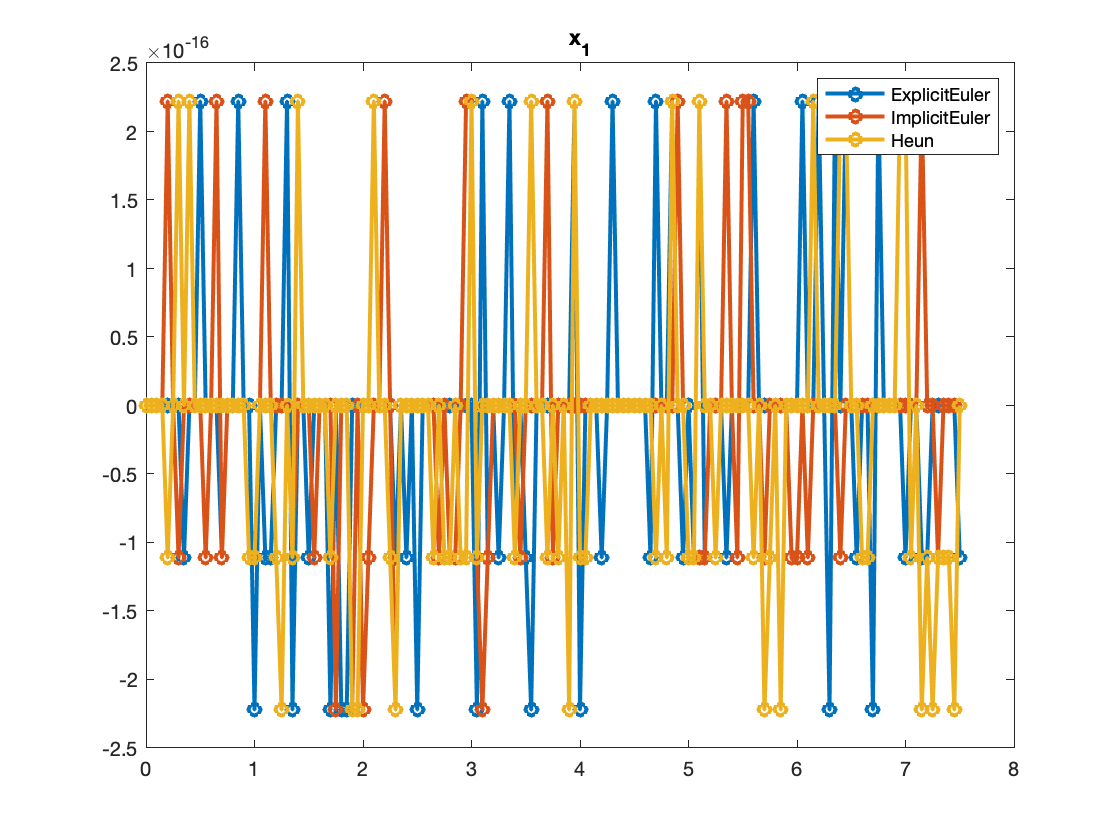

h = figure();
plot( tt, x1_1.^2+y1_1.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
hold on;
plot( tt, x1_2.^2+y1_2.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
plot( tt, x1_3.^2+y1_3.^2-ell^2, '-o', 'MarkerSize', 6, 'Linewidth', 2 );
legend(LEGEND);
title('x_1');

### Make animation of the solution

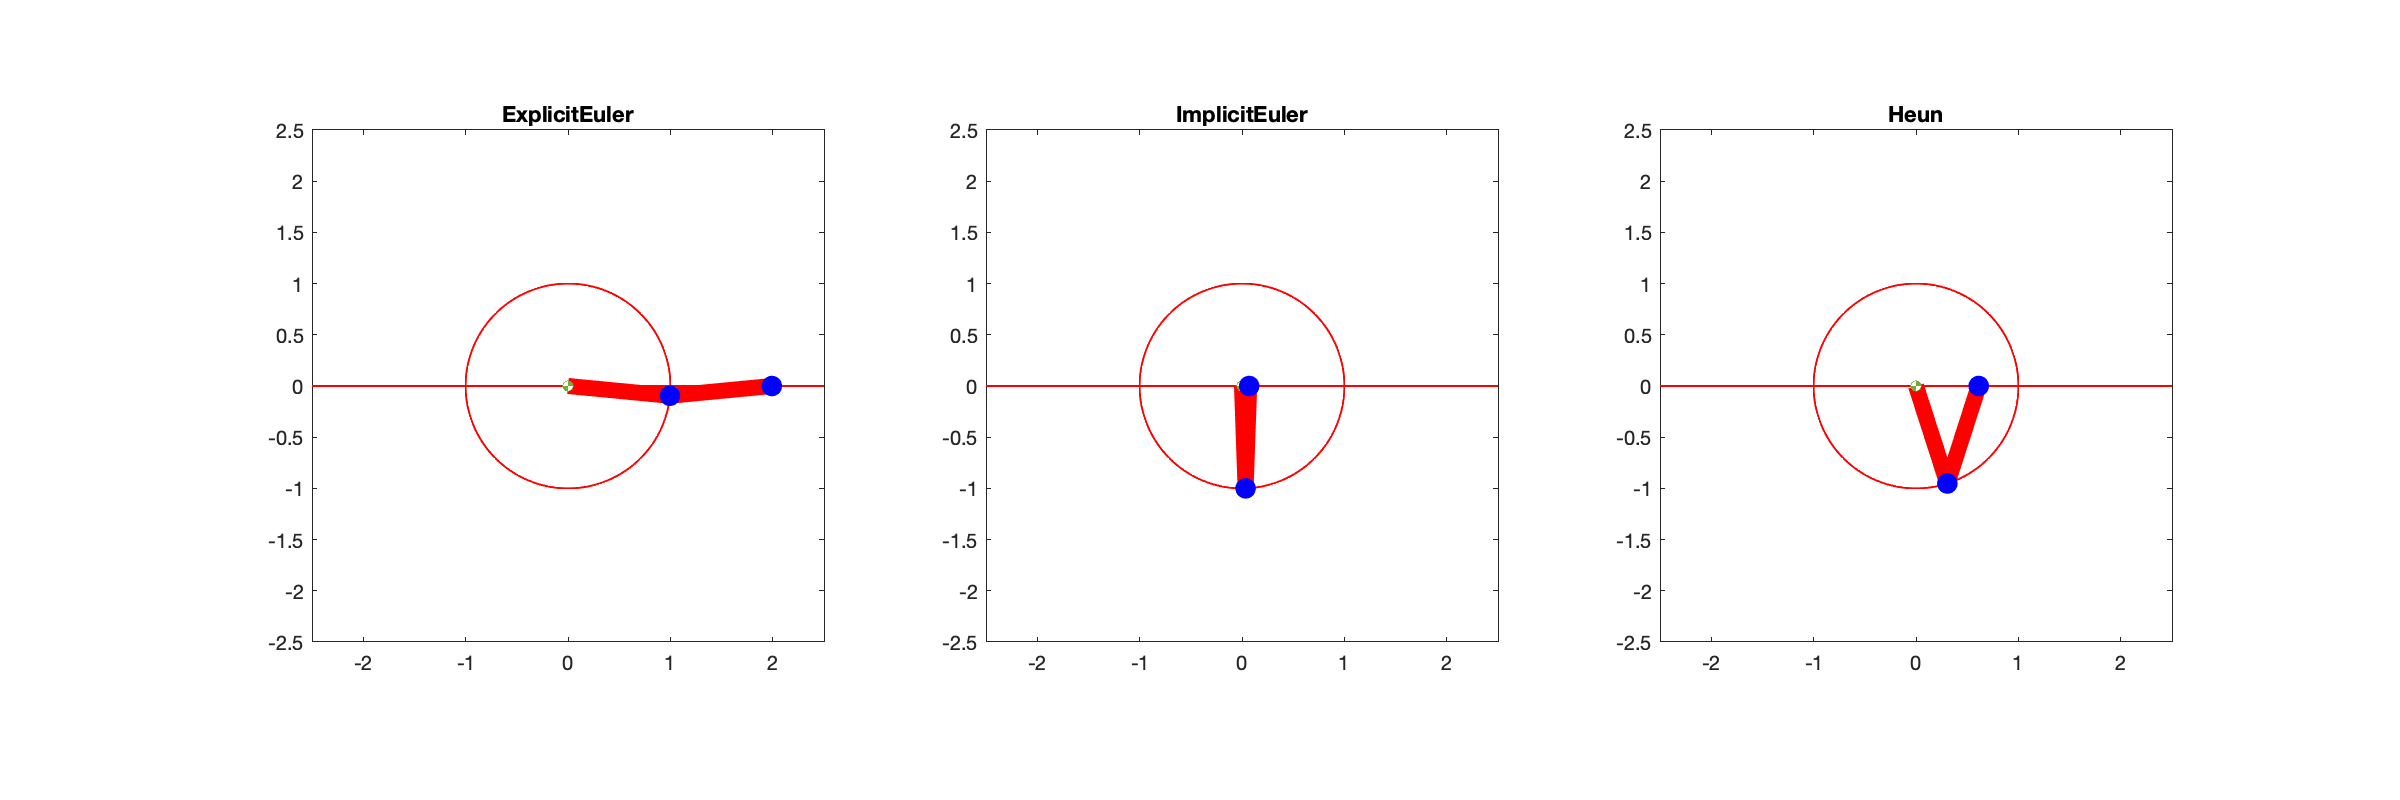

if true
  figure('Position', [1 1 1200 400]);
  for k=1:5:length(tt)
    subplot(1,3,1);
    ode.plot( tt(k), sol_1(:,k));
    title(LEGEND{1});
    subplot(1,3,2);
    ode.plot( tt(k), sol_2(:,k));
    title(LEGEND{2});
    subplot(1,3,3);
    ode.plot( tt(k), sol_3(:,k));
    title(LEGEND{3});
    drawnow limitrate;
    pause(0.01);
  end
end